# Baja SAE Statistical Analysis

% loading results from .mat file
allResults = struct2cell(load('Results_Tables_Updated.mat'))

allResults = 39×1 cell array
    {100×17 table}
    { 75×15 table}
    {141×16 table}
    {120×17 table}
    {115×18 table}
    { 93×18 table}
    { 95×19 table}
    {120×18 table}
    {100×18 table}
    { 99×18 table}
    {100×17 table}
    { 89×18 table}
    {100×17 table}
    { 59×18 table}
    {115×18 table}
    { 79×18 table}


% example of imported data
allResults{1} 

ans = 100×17 table
    VarName1    Event                     Overall                                 SDSM2007                VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17
    ________    _____    __________________________________________    _______________________________    ________    ________    ________    ________    ________    _________    _________    _________    ________

## Data Cleaning

% fixing results in one table
VarName17 = zeros(120, 1);
allResults{8} = [allResults{8}(:, 1:16), array2table(VarName17), allResults{8}(:, 17:18)];

### List of Events at Each Competition

% arrays for storing which events occured at which competitions
sledPull = [23 25 27 29 30 32 34 35 38 41 44 50 53 56 58];
salesPres = [22 26 28 31 36 37 40 43:60];
techEvent = [28 29 30];
techPen = [25 26 27];
techPenEnd = [22 23 24];
waterManeu = [23 27 33 35];
rockCrawl = [22 26 28 31 36 37 40 45 46 54 57]; %comes after hill climb in dataset, regular s&t comes before
mudBog = [23 29 38];

### Competition Names and Numbers

% filling row with number associated with each comp(first comp of 2000 is 1)
for i = 1:size(allResults, 1)
    allResults{i, 2} = 21 + i;
end

% array storing names of each comp
compNames = ["SDSM 2007", "UCF 2007", "RIT 2007", "Montreal 2008", "Illinois 2008", "Tennessee 2008", "Oregon 2009", "Wisconsin 2009",  "Alabama 2009", "Washington 2010", "Carolina 2010", "Rochester 2010", "Kansas 2011", "Birmingham 2011", "Illinois 2011", "Oregon 2012", "Wisconsin 2012", "Auburn 2012", "Washington 2013", "Tennessee 2013", "Rochester 2013", "UTEP 2014", "Kansas 2014","Illinois 2014", "Oregon 2015", "Auburn 2015", "Maryland 2015", "California 2016", "Tennessee 2016", "Rochester 2016", "California 2017", "Kansas 2017", "Illinois 2017", "Maryland 2018", "Kansas 2018", "Oregon 2018", "Tennessee 2019", "California 2019", "Rochester 2019"]

compNames = 1×39 string array
    "SDSM 2007"    "UCF 2007"    "RIT 2007"    "Montreal 2008"    "Illinois 2008"    "Tennessee 2008"    "Oregon 2009"    "Wisconsin 2009"    "Alabama 2009"    "Washington 2010"    "Carolina 2010"    "Rochester 2010"    "Kansas 2011"    "Birmingham 2011"    "Illinois 2011"    "Oregon 2012"    "Wisconsin 2012"    "Auburn 2012"    "Washington 2013"    "Tennessee 2013"    "Rochester 2013"    "UTEP 2014"    "Kansas 2014"    "Illinois 2014"    "Oregon 2015"    "Auburn 2015"    "Maryland 2015"    "California 2016"    "Tennessee 2016"    "Rochester 2016"    "California 2017"    "Kansas 2017"    "Illinois 2017"    "Maryland 2018"    "Kansas 2018"    "Oregon 2018"    "Tennessee 2019"    "California 2019"    "Rochester 2019"



% adding competition names to cell array
for i = 1:size(compNames, 2)
    allResults{i, 3} = compNames(i);
end

### Naming Event Columns

%for loops for naming columns. fills based on how SAE seems to fill the
%tables. competition 23 doesn't follow the pattern though
for i = 1:size(allResults, 1)
    if allResults{i, 2} ~= 23
        offset = 0;
        
        allResults{i, 1}.Properties.VariableNames([1:9]) = {'overallRank' 'carNumber' 'universityName' 'teamName' 'overallScore' 'overallDynamic' 'overallStatic' 'costScore' 'designScore'};
        
        if ismember(allResults{i, 2}, salesPres)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'salesScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, techPen)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'techPenalty'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, techEvent)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'techScore'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames([10 + offset, 11 + offset]) = {'accelScore', 'landManeuScore'};
        
        if ismember(allResults{i, 2}, mudBog)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'mudBogScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, rockCrawl)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'rockCrawlScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, sledPull)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'sledPullScore'};
        else
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'hillClimbScore'};
        end
        
        if ~ismember(allResults{i, 2}, rockCrawl)
            allResults{i, 1}.Properties.VariableNames(13 + offset) = {'susTracScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, waterManeu)
            allResults{i, 1}.Properties.VariableNames(13 + offset) = {'waterManeuScore'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames(13 + offset) = {'enduroScore'};
        
        if ismember(allResults{i, 2}, techPenEnd)
            allResults{i, 1}.Properties.VariableNames(14 + offset) = {'techPenalty'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames(14 + offset) = {'penalty'};
        
        if ~ismember(allResults{i, 2}, techPen) && ~ismember(allResults{i, 2}, techPenEnd)
            allResults{i, 1}.Properties.VariableNames(15 + offset) = {'registered'};
            allResults{i, 1}.Properties.VariableNames(16 + offset) = {'techPassed'};
        elseif ismember(allResults{i, 2}, techPen)
             allResults{i, 1}.Properties.VariableNames(15 + offset) = {'registered'};
        end
    else
        allResults{i, 1}.Properties.VariableNames = {'overallRank' 'carNumber' 'universityName' 'teamName' 'overallScore' 'designScore' 'costScore' 'accelScore' 'mudBogScore' 'susTracScore' 'waterManeuScore' 'sledPullScore' 'enduroScore' 'techPenalty' 'penalty'};
    end
    
      allResults{i, 1}.universityName = convertCharsToStrings(allResults{i, 1}.universityName);
end

allResults{1}

ans = 100×17 table
    overallRank    carNumber                  universityName                             teamName                overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    accelScore    landManeuScore    rockCrawlScore    hillClimbScore    enduroScore    techPenalty    penalty
    ___________    _________    __________________________________________    _______________________________    ____________    ______________    _____________    _________    ___________    __________    

### Cleaning University Names Data

% Paired list of names that refer to same uni

wrongNames = ["Christian Brothers College" "Arizona State Univ - Polytechnic" "California Polytechnic State Univ-SLO" "City College of the City Univ of NY"; 
              "Christian Brothers Univ" "Arizona State Univ Polytechnic" "California State Poly Univ-San Luis Obis" "City College of New York"];

% List of all universities that have participated in Baja SAE competitions

allUnis = getParticipatingUnis(allResults, wrongNames);

## Using the Database

% Get results from any competition
getCompResults(allResults, 28)

ans = 95×19 table
    overallRank    carNumber                universityName                         teamName            overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    techScore    accelScore    landManeuScore    rockCrawlScore    hillClimbScore    enduroScore    penalty    registered     techPassed
    ___________    _________    _______________________________________    ________________________    ____________    ______________    _____________    _________    ___________

% tells us which competition we're looking at
compNames(28)

ans = "California 2016"

% Find all comps a team attended with their results

warning('off') % function does some sketchy stuff with tables
tempResults = getCompsAttended(allResults, wrongNames, "Univ of Illinois - Urbana Champaign", allUnis)

tempResults = 30×26 table
        compName         overallRank    carNumber               universityName                     teamName         overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    techScore    accelScore    landManeuScore    rockCrawlScore    mudBogScore    hillClimbScore    sledPullScore    susTracScore    waterManeuScore    enduroScore    techPenalty    penalty    registered    techPassed    PassedTechOnTime
    _________________    ___________    _______

% write team results to table

writetable(tempResults, 'Output Tables\UIUCAllResults.xlsx')

% Grab Iron Team Award results for a given season 

wrongNamesTwo = strings; % university name replacement doesn't quite work yet
getIronTeamResults(allResults, wrongNamesTwo, "2019")

ans = 20×2 cell array
    {'Univ of Michigan - Ann Arbor'       }    {'2819.09'}
    {'Ecole de Technologie Superieure'    }    {'2618.96'}
    {'Rochester Institute of Technology'  }    {'2471.58'}
    {'Cornell Univ'                       }    {'2443.57'}
    {'San Diego State Univ'               }    {'2419.61'}
    {'Univ of Akron'                      }    {'2395.99'}
    {'Univ of Maryland - Baltimore County'}    {'2337.35'}
    {'Johns Hopkins Univ'                 }    {'2009.67'}
    {'Case Western Reserve Univ'          }    {'2006.46'}
    {'Univ of Nebraska - Lincoln'         }    {'1978.42'}
    {'Univ of Nevada - Las Vegas'         }    {'1972.71'}
    {'Clarkson University'                }    {'1809.46'}
    {'Univ of Illinois - Urbana Champaign'}    {'1728.32'}
    {'Iowa State Univ'                    }    {'1714.48'}
    {'New Jersey Institute of Technology' }    {'1588.22'}
    {'Queen's Univ'                       }    {'1531.26'}
    {'Virginia Tech'              

% Ranks teams by highest average score for a given season

getAvgSeasonResults(allResults, wrongNamesTwo, "2017")

ans = 224×2 cell array
    {'West Virginia Univ'                   }    {'NaN'     }
    {'Univ of Michigan - Ann Arbor'         }    {'879.6167'}
    {'Oregon State Univ'                    }    {'823.885' }
    {'Ecole De Technologie Superieure'      }    {'803.13'  }
    {'Univ of Wisconsin - Madison'          }    {'774.05'  }
    {'Rochester Institute of Technology'    }    {'749.27'  }
    {'Northeastern Univ'                    }    {'745.615' }
    {'Cornell Univ'                         }    {'739.46'  }
    {'Univ of Akron'                        }    {'737'     }
    {'Universidad De La Salle Bajio'        }    {'731.74'  }
    {'New Jersey Institute of Technology'   }    {'714.23'  }
    {'Queen's Univ - Ontario Canada'        }    {'705.1067'}
    {'Georgia Southern Univ'                }    {'703.51'  }
    {'Brigham Young Univ'                   }    {'703.22'  }
    {'Government College of Engrg Pune'     }    {'702.73'  }
    {'California Polytechnic State Univ-SLO'}  

% Ranks teams by average results across multiple seasons, with min
% competition threshold

getAvgResults(allResults, wrongNamesTwo, ["2017" "2018" "2019"], 5)

ans = 54×3 cell array
    {'Univ of Michigan - Ann Arbor'         }    {'887.0133'}    {[9]}
    {'Ecole De Technologie Superieure'      }    {'833.2633'}    {[9]}
    {'Cornell Univ'                         }    {'830.2662'}    {[8]}
    {'Rochester Institute of Technology'    }    {'826.7789'}    {[9]}
    {'Oregon State Univ'                    }    {'816.62'  }    {[5]}
    {'Univ of Akron'                        }    {'789.7544'}    {[9]}
    {'San Diego State Univ'                 }    {'759.6189'}    {[9]}
    {'California Polytechnic State Univ-SLO'}    {'724.5717'}    {[6]}
    {'Univ of Maryland - Baltimore County'  }    {'712.6037'}    {[8]}
    {'Northeastern Univ'                    }    {'682.2757'}    {[7]}
    {'Pennsylvania College of Technology'   }    {'673.815' }    {[6]}
    {'Case Western Reserve Univ'            }    {'670.6662'}    {[8]}
    {'Univ of Nebraska - Lincoln'           }    {'666.85'  }    {[9]}
    {'Université Laval'                     }    {'653.

% Average results again, but this time recording average place

getAvgPlace(allResults, wrongNamesTwo, ["2010" "2011" "2012" "2013" "2014" "2015" "2016" "2017" "2018" "2019"], 10)

ans = 120×3 cell array
    {'Oregon State Univ'                  }    {'4.2353' }    {[17]}
    {'Cornell Univ'                       }    {'4.84'   }    {[25]}
    {'Rochester Institute of Technology'  }    {'6.2'    }    {[30]}
    {'Ecole De Technologie Superieure'    }    {'6.6333' }    {[30]}
    {'Universite Laval'                   }    {'10'     }    {[13]}
    {'Univ of Maryland - Baltimore County'}    {'16.2759'}    {[29]}
    {'San Diego State Univ'               }    {'17.7222'}    {[18]}
    {'Univ of Wisconsin - Madison'        }    {'17.8824'}    {[17]}
    {'Universidad De La Salle Bajio'      }    {'18'     }    {[10]}
    {'Northeastern Univ'                  }    {'18.1304'}    {[23]}
    {'Ohio Northern Univ'                 }    {'19.48'  }    {[25]}
    {'Univ of Nebraska - Lincoln'         }    {'20.7083'}    {[24]}
    {'Pennsylvania College of Technology' }    {'21.0714'}    {[14]}
    {'McGill Univ'                        }    {'21.2'   }    {[20]}
    {'Georg

% Find the closest competitions ever

getClosestComps(allResults)

ans = 10×4 cell array
    {["Maryland 2018"  ]}    {["Rochester Institute of Technology"]}    {[931.9100]}    {[8.2626e-04]}
    {["Carolina 2010"  ]}    {["Universite Laval"                 ]}    {[911.9000]}    {[    0.0013]}
    {["Tennessee 2013" ]}    {["Cornell Univ"                     ]}    {[845.6200]}    {[    0.0027]}
    {["Tennessee 2008" ]}    {["Queen's Univ - Ontario Canada"    ]}    {[855.7700]}    {[    0.0049]}
    {["Wisconsin 2009" ]}    {["Oregon State Univ"                ]}    {[942.9200]}    {[    0.0061]}
    {["SDSM 2007"      ]}    {[" Auburn University"               ]}    {[855.2800]}    {[    0.0083]}
    {["Illinois 2017"  ]}    {["Ecole De Technologie Superieure"  ]}    {[886.7700]}    {[    0.0112]}
    {["Kansas 2014"    ]}    {["Centro Universitario Da FEI"      ]}    {[885.6800]}    {[    0.0117]}
    {["Illinois 2014"  ]}    {["Cornell Univ"                     ]}    {[930.0300]}    {[    0.0128]}
    {["California 2017"]}    {["Ecole De Technologi

### Flexible Result Correlation

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)       8.58      8.0001    1.0725       0.28855
    x1             0.60145     0.15009    4.0073    0.00020036


Number of observations: 53, Error degrees of freedom: 51
Root Mean Squared Error: 18
R-squared: 0.239,  Adjusted R-Squared: 0.225
F-statistic vs. constant model: 16.1, p-value = 0.0002

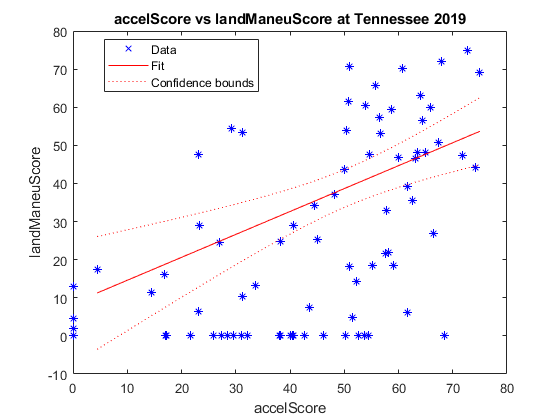

% Graphs results from any competition against eachother

linModel = graphResults2D(allResults, 58, "accelScore", "landManeuScore");

% Can easily grab the r-squared (adjusted better)
rSqr = linModel.Rsquared.Adjusted

rSqr = 0.2246

### 3D Correlation

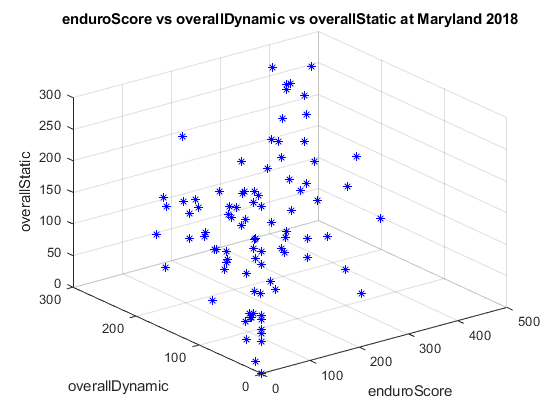


% Graph 3 sets of scores together

graphResults3D(allResults, 55, "enduroScore", "overallDynamic", "overallStatic");

## Calculating Correlation of Results

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      25.806      4.0368    6.3927    1.3622e-08
    x1             0.047075    0.008319    5.6588    2.8115e-07


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 14.2
R-squared: 0.305,  Adjusted R-Squared: 0.295
F-statistic vs. constant model: 32, p-value = 2.81e-07

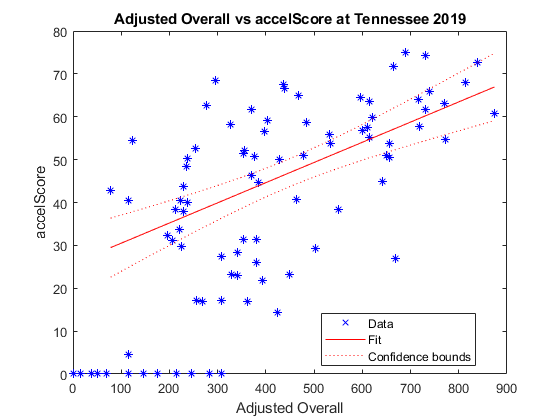

linModel2 = findResultCorrelation(allResults, 58, "accelScore");

% Once again easy to grab R-Squared
linModel2.Rsquared.Adjusted

ans = 0.2954

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     -64.81      28.368    -2.2846       0.02502
    x1             0.84212     0.08489     9.9202    1.5745e-15


Number of observations: 81, Error degrees of freedom: 79
Root Mean Squared Error: 78.5
R-squared: 0.555,  Adjusted R-Squared: 0.549
F-statistic vs. constant model: 98.4, p-value = 1.57e-15

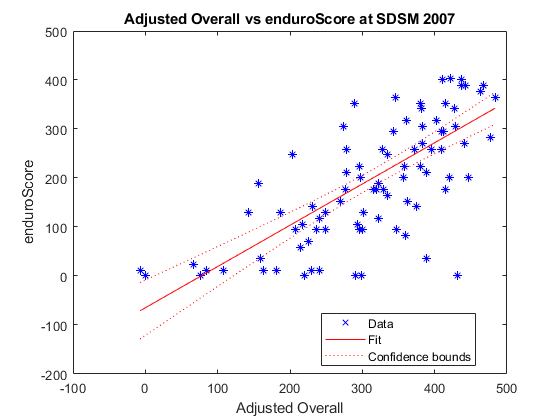

i = 22

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     27.605      43.505    0.63453       0.52869
    x1             0.52134     0.12568     4.1483    0.00013275


Number of observations: 51, Error degrees of freedom: 49
Root Mean Squared Error: 94.7
R-squared: 0.26,  Adjusted R-Squared: 0.245
F-statistic vs. constant model: 17.2, p-value = 0.000133

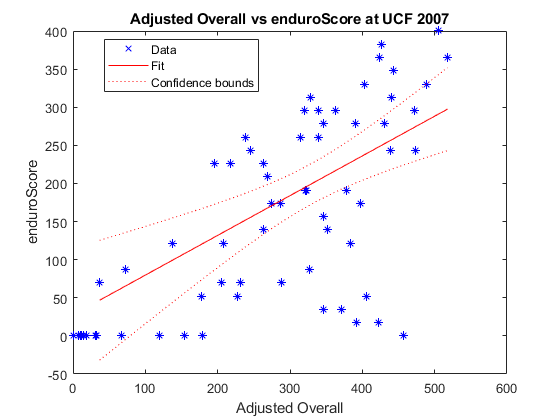

i = 23

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)    -74.958       30.116    -2.489     0.014241
    x1             0.88086     0.081473    10.812    3.177e-19


Number of observations: 117, Error degrees of freedom: 115
Root Mean Squared Error: 87.1
R-squared: 0.504,  Adjusted R-Squared: 0.5
F-statistic vs. constant model: 117, p-value = 3.18e-19

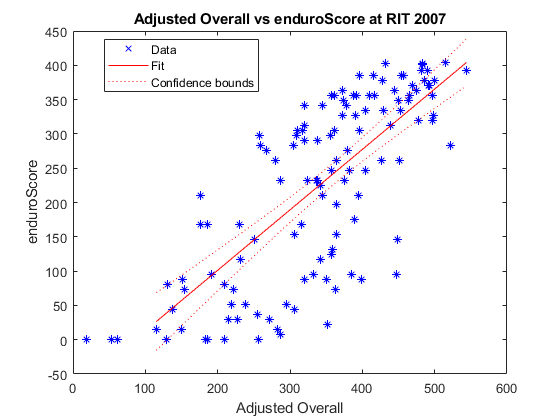

i = 24

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       211.63     16.009       13.22    6.7835e-23
    x1             -0.037236    0.04547    -0.81892       0.41497


Number of observations: 93, Error degrees of freedom: 91
Root Mean Squared Error: 107
R-squared: 0.00732,  Adjusted R-Squared: -0.00359
F-statistic vs. constant model: 0.671, p-value = 0.415

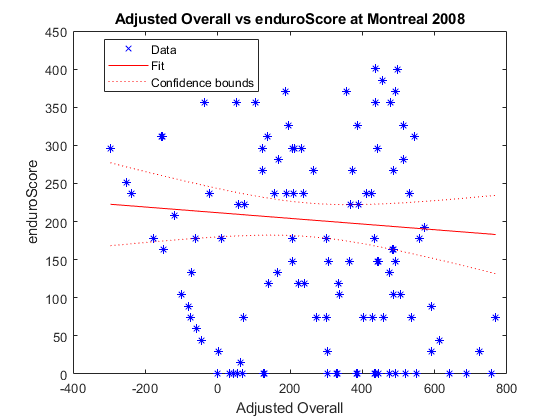

i = 25

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat      pValue  
                   ________    ________    _______    _________

    (Intercept)     28.526       30.811    0.92585      0.35806
    x1             0.45959     0.087499     5.2525    1.888e-06


Number of observations: 65, Error degrees of freedom: 63
Root Mean Squared Error: 86.5
R-squared: 0.305,  Adjusted R-Squared: 0.294
F-statistic vs. constant model: 27.6, p-value = 1.89e-06

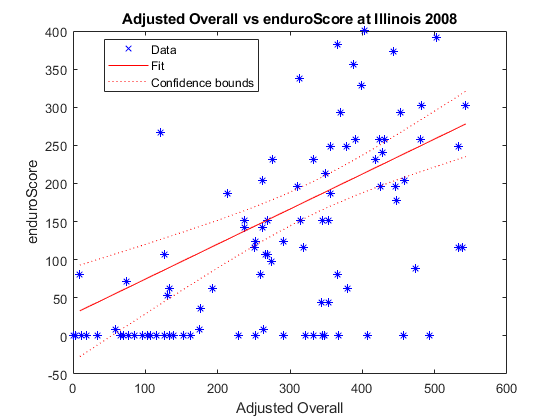

i = 26

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     9.5256       38.99    0.24431        0.8081
    x1             0.45793     0.10866     4.2142    0.00011899


Number of observations: 47, Error degrees of freedom: 45
Root Mean Squared Error: 101
R-squared: 0.283,  Adjusted R-Squared: 0.267
F-statistic vs. constant model: 17.8, p-value = 0.000119

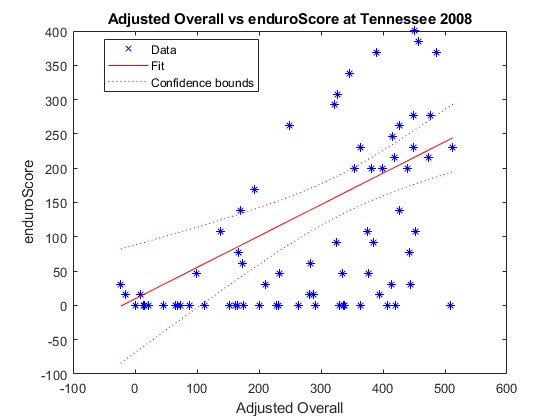

i = 27

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -37.955       35.084    -1.0818       0.28388
    x1             0.66833     0.097375     6.8635    5.3705e-09


Number of observations: 59, Error degrees of freedom: 57
Root Mean Squared Error: 83.5
R-squared: 0.452,  Adjusted R-Squared: 0.443
F-statistic vs. constant model: 47.1, p-value = 5.37e-09

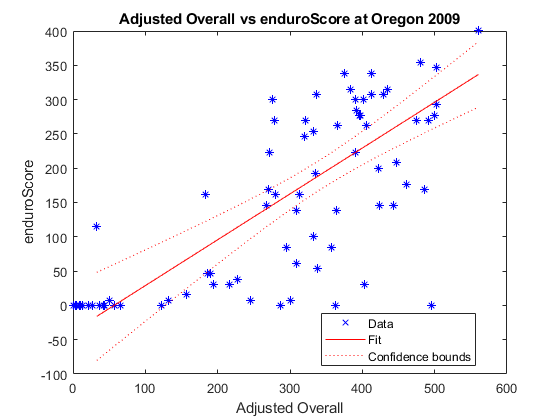

i = 28

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     13.141       34.216    0.38406       0.70183
    x1             0.48612     0.083656      5.811    9.0581e-08


Number of observations: 93, Error degrees of freedom: 91
Root Mean Squared Error: 91.3
R-squared: 0.271,  Adjusted R-Squared: 0.263
F-statistic vs. constant model: 33.8, p-value = 9.06e-08

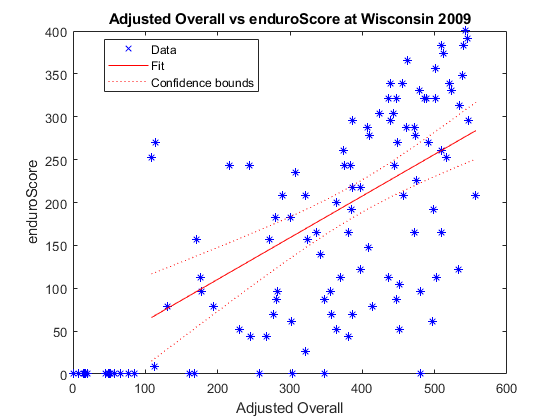

i = 29

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________

    (Intercept)    -23.201       38.513    -0.60242       0.54878
    x1             0.51436     0.093906      5.4774    6.0042e-07


Number of observations: 74, Error degrees of freedom: 72
Root Mean Squared Error: 86.9
R-squared: 0.294,  Adjusted R-Squared: 0.284
F-statistic vs. constant model: 30, p-value = 6e-07

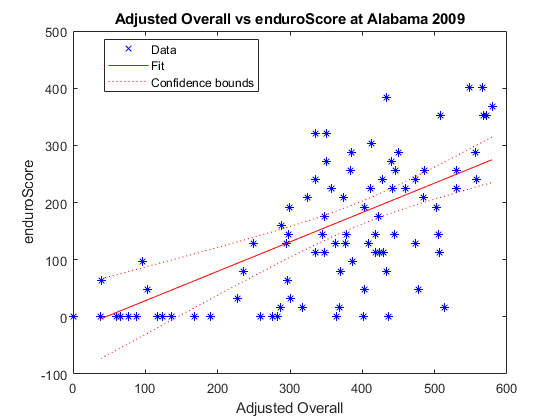

i = 30

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)    -32.704      39.702    -0.82373        0.4126
    x1             0.76323     0.11539      6.6145    4.2234e-09


Number of observations: 80, Error degrees of freedom: 78
Root Mean Squared Error: 97.3
R-squared: 0.359,  Adjusted R-Squared: 0.351
F-statistic vs. constant model: 43.8, p-value = 4.22e-09

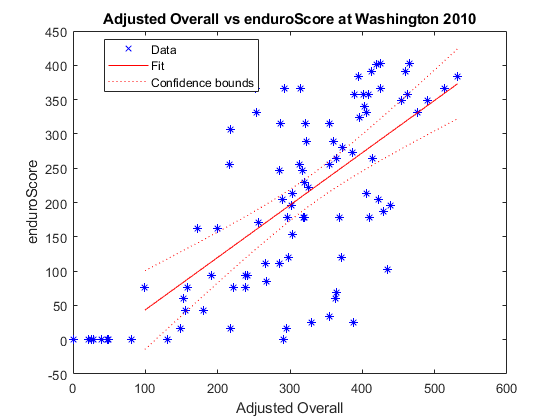

i = 31

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)    -6.7065      46.938    -0.14288       0.88675
    x1             0.61656     0.12652      4.8732    5.4614e-06


Number of observations: 82, Error degrees of freedom: 80
Root Mean Squared Error: 102
R-squared: 0.229,  Adjusted R-Squared: 0.219
F-statistic vs. constant model: 23.7, p-value = 5.46e-06

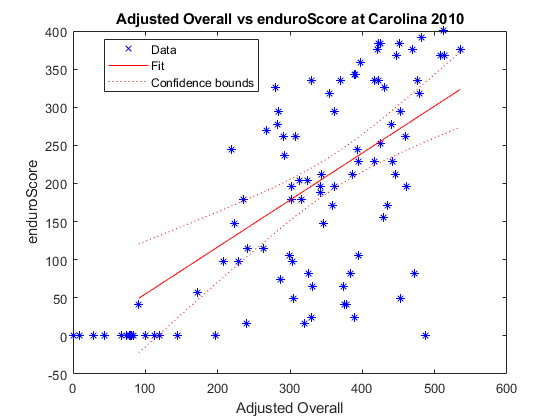

i = 32

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     43.897      51.107    0.85892       0.39418
    x1             0.53573     0.13387      4.002    0.00019287


Number of observations: 56, Error degrees of freedom: 54
Root Mean Squared Error: 97.4
R-squared: 0.229,  Adjusted R-Squared: 0.214
F-statistic vs. constant model: 16, p-value = 0.000193

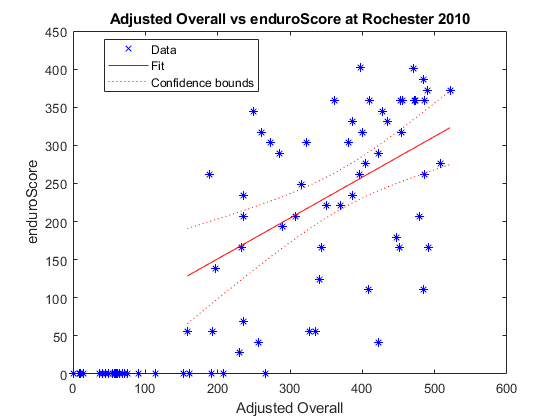

i = 33

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     19.904      36.461    0.5459       0.58678
    x1             0.55286     0.10678    5.1773    1.8695e-06


Number of observations: 76, Error degrees of freedom: 74
Root Mean Squared Error: 99.3
R-squared: 0.266,  Adjusted R-Squared: 0.256
F-statistic vs. constant model: 26.8, p-value = 1.87e-06

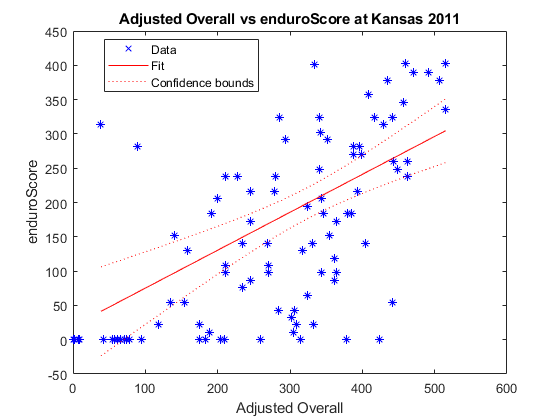

i = 34

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     -31.56      38.648    -0.8166       0.41984
    x1             0.62798     0.10573     5.9394    1.0322e-06


Number of observations: 36, Error degrees of freedom: 34
Root Mean Squared Error: 76.4
R-squared: 0.509,  Adjusted R-Squared: 0.495
F-statistic vs. constant model: 35.3, p-value = 1.03e-06

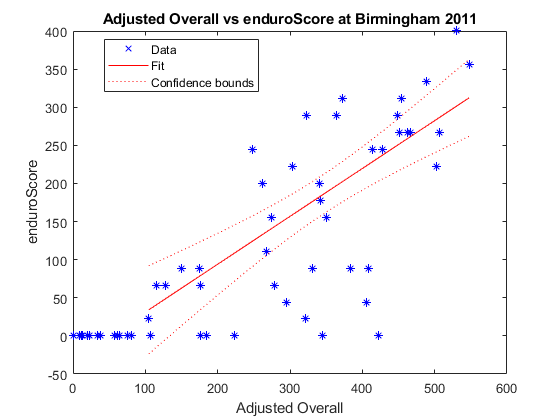

i = 35

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     20.162       30.907    0.65235       0.51607
    x1             0.44981     0.085628     5.2531    1.2351e-06


Number of observations: 81, Error degrees of freedom: 79
Root Mean Squared Error: 92.1
R-squared: 0.259,  Adjusted R-Squared: 0.249
F-statistic vs. constant model: 27.6, p-value = 1.24e-06

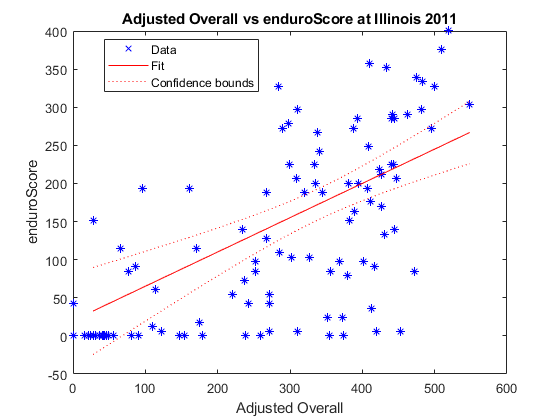

i = 36

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     46.438      43.222    1.0744       0.28812
    x1             0.56311     0.12955    4.3467    7.3515e-05


Number of observations: 49, Error degrees of freedom: 47
Root Mean Squared Error: 94.5
R-squared: 0.287,  Adjusted R-Squared: 0.272
F-statistic vs. constant model: 18.9, p-value = 7.35e-05

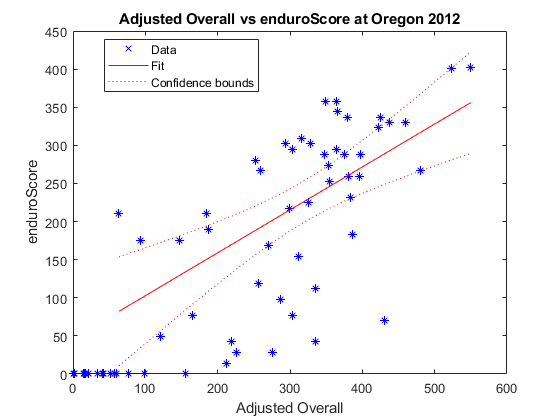

i = 37

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________

    (Intercept)    -11.346       29.328    -0.38685       0.69975
    x1             0.67752     0.084655      8.0033    3.3361e-12


Number of observations: 95, Error degrees of freedom: 93
Root Mean Squared Error: 84
R-squared: 0.408,  Adjusted R-Squared: 0.401
F-statistic vs. constant model: 64.1, p-value = 3.34e-12

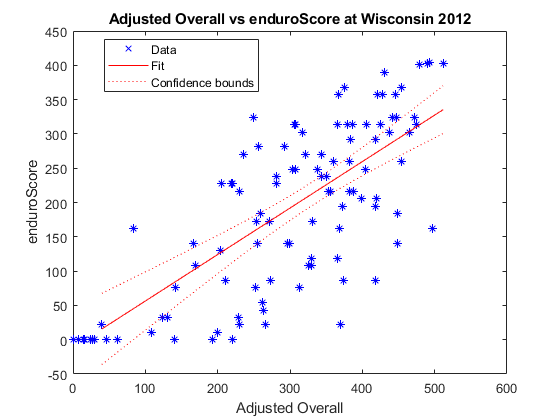

i = 38

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     53.713      36.317     1.479       0.14404
    x1             0.44485     0.10235    4.3464    5.0546e-05


Number of observations: 66, Error degrees of freedom: 64
Root Mean Squared Error: 101
R-squared: 0.228,  Adjusted R-Squared: 0.216
F-statistic vs. constant model: 18.9, p-value = 5.05e-05

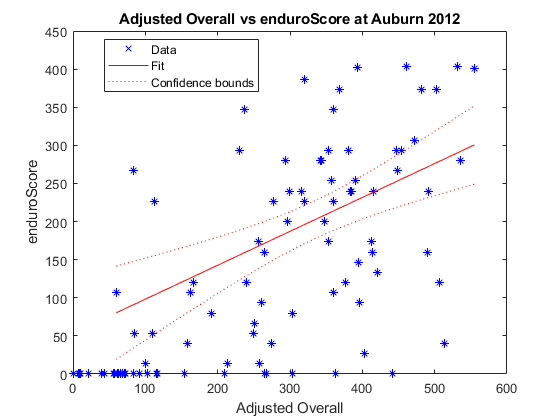

i = 39

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     74.471       45.51    1.6363      0.10758
    x1             0.42072     0.13375    3.1455    0.0026961


Number of observations: 56, Error degrees of freedom: 54
Root Mean Squared Error: 101
R-squared: 0.155,  Adjusted R-Squared: 0.139
F-statistic vs. constant model: 9.89, p-value = 0.0027

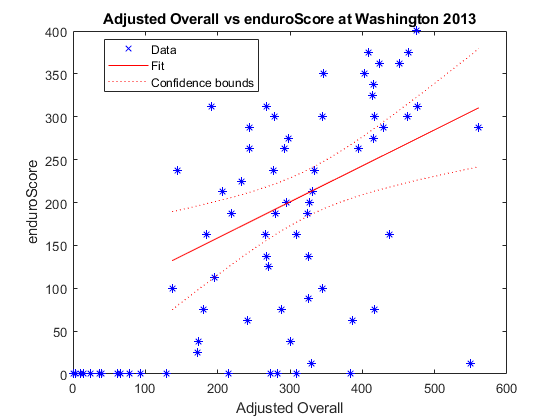

i = 40

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)     82.741       28.473    2.9059    0.0048109
    x1             0.49296     0.094995    5.1894    1.742e-06


Number of observations: 77, Error degrees of freedom: 75
Root Mean Squared Error: 100
R-squared: 0.264,  Adjusted R-Squared: 0.254
F-statistic vs. constant model: 26.9, p-value = 1.74e-06

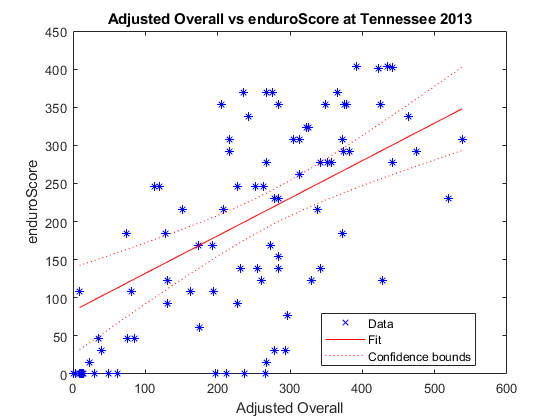

i = 41

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     17.603       25.691    0.68515        0.4953
    x1             0.69503     0.078862     8.8132    2.7477e-13


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 79.1
R-squared: 0.502,  Adjusted R-Squared: 0.496
F-statistic vs. constant model: 77.7, p-value = 2.75e-13

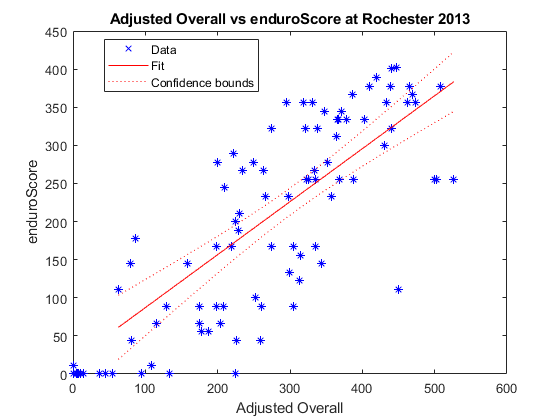

i = 42

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     24.782       24.786    0.99986       0.32073
    x1             0.63117     0.081293     7.7641    4.2232e-11


Number of observations: 74, Error degrees of freedom: 72
Root Mean Squared Error: 84.5
R-squared: 0.456,  Adjusted R-Squared: 0.448
F-statistic vs. constant model: 60.3, p-value = 4.22e-11

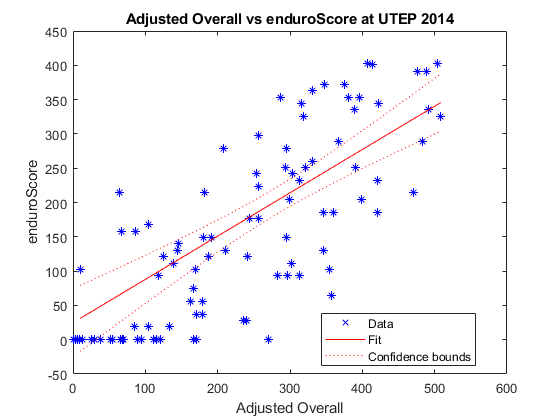

i = 43

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     40.583      29.482    1.3765       0.17259
    x1             0.52281     0.09539    5.4807    5.0286e-07


Number of observations: 80, Error degrees of freedom: 78
Root Mean Squared Error: 96.6
R-squared: 0.278,  Adjusted R-Squared: 0.269
F-statistic vs. constant model: 30, p-value = 5.03e-07

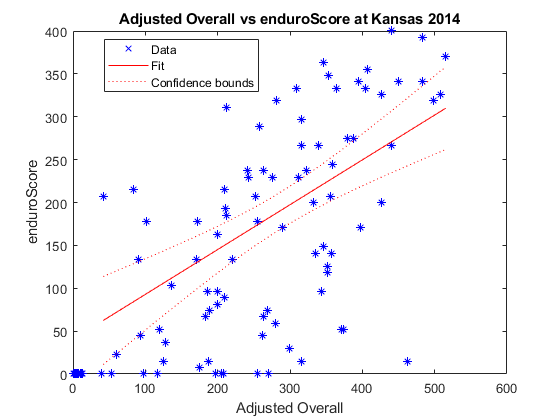

i = 44

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     5.0031       27.266    0.18349       0.85487
    x1             0.55442     0.085381     6.4934    6.0417e-09


Number of observations: 84, Error degrees of freedom: 82
Root Mean Squared Error: 86.9
R-squared: 0.34,  Adjusted R-Squared: 0.332
F-statistic vs. constant model: 42.2, p-value = 6.04e-09

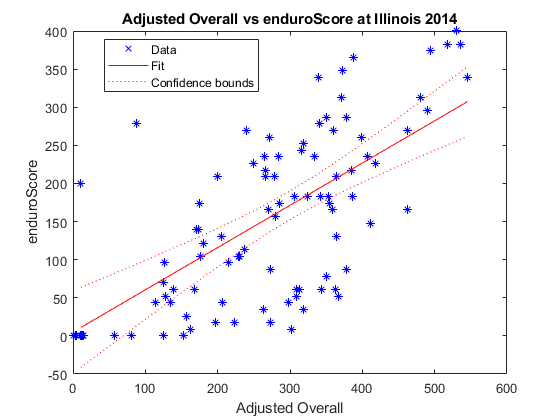

i = 45

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     19.082       26.333    0.72462       0.47088
    x1             0.64276     0.084349     7.6203    5.4582e-11


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 90
R-squared: 0.43,  Adjusted R-Squared: 0.423
F-statistic vs. constant model: 58.1, p-value = 5.46e-11

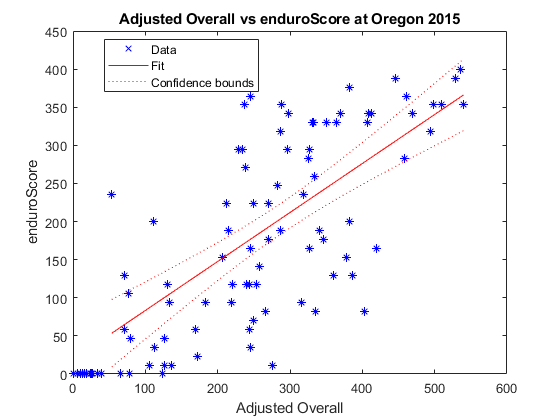

i = 46

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     52.431       30.331    1.7286      0.088101
    x1             0.44227     0.084795    5.2158    1.6462e-06


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 84.6
R-squared: 0.271,  Adjusted R-Squared: 0.262
F-statistic vs. constant model: 27.2, p-value = 1.65e-06

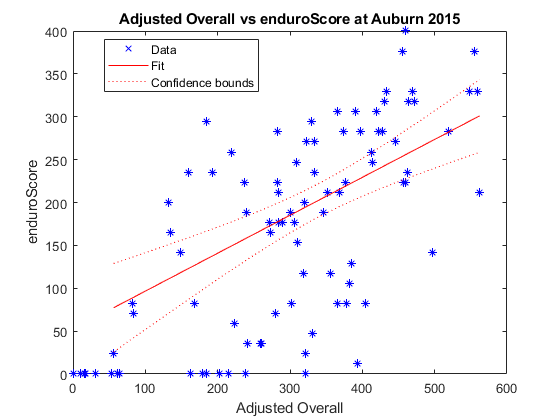

i = 47

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________

    (Intercept)    -6.2571       30.952    -0.20216       0.84036
    x1             0.61444     0.082226      7.4726    1.3727e-10


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 79.9
R-squared: 0.433,  Adjusted R-Squared: 0.426
F-statistic vs. constant model: 55.8, p-value = 1.37e-10

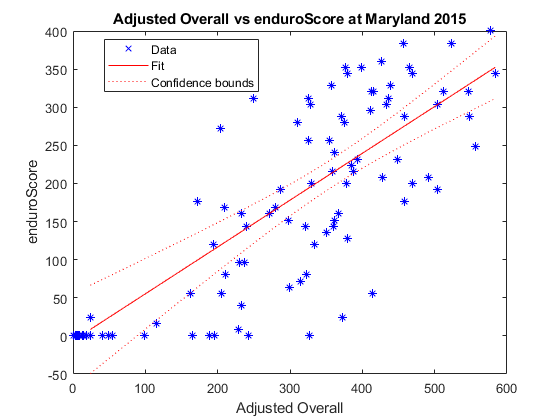

i = 48

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     77.229      30.231    2.5546      0.012602
    x1             0.45027     0.08818    5.1063    2.3141e-06


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 94
R-squared: 0.253,  Adjusted R-Squared: 0.243
F-statistic vs. constant model: 26.1, p-value = 2.31e-06

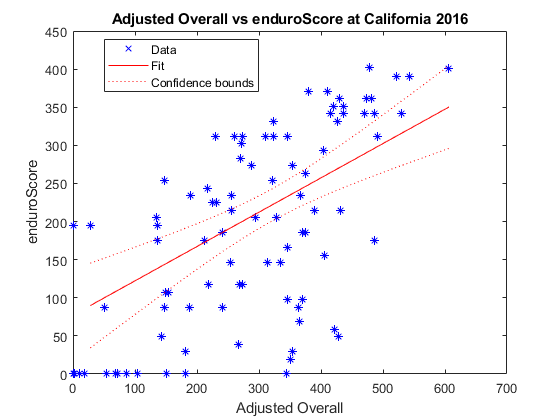

i = 49

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     16.678       27.151    0.61426       0.54085
    x1             0.58785     0.086016     6.8342    1.7101e-09


Number of observations: 79, Error degrees of freedom: 77
Root Mean Squared Error: 90.2
R-squared: 0.378,  Adjusted R-Squared: 0.369
F-statistic vs. constant model: 46.7, p-value = 1.71e-09

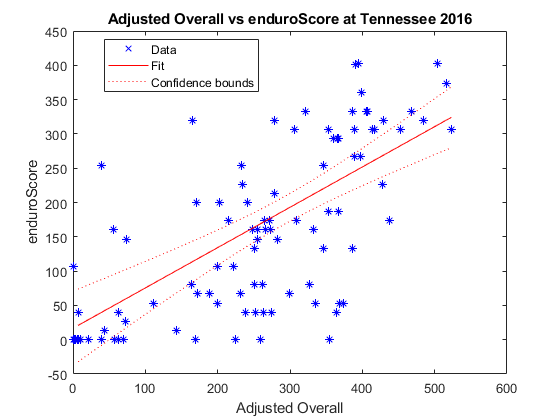

i = 50

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     30.003       30.752    0.97563       0.33202
    x1             0.55592     0.087971     6.3194    1.1611e-08


Number of observations: 87, Error degrees of freedom: 85
Root Mean Squared Error: 91.8
R-squared: 0.32,  Adjusted R-Squared: 0.312
F-statistic vs. constant model: 39.9, p-value = 1.16e-08

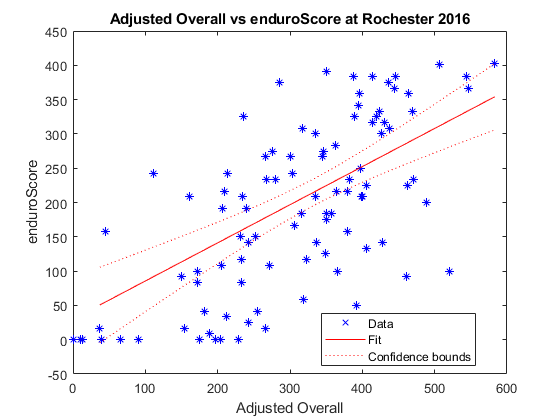

i = 51

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     106.57       28.845    3.6945    0.00043342
    x1             0.37142     0.093751    3.9618    0.00017685


Number of observations: 72, Error degrees of freedom: 70
Root Mean Squared Error: 94.6
R-squared: 0.183,  Adjusted R-Squared: 0.171
F-statistic vs. constant model: 15.7, p-value = 0.000177

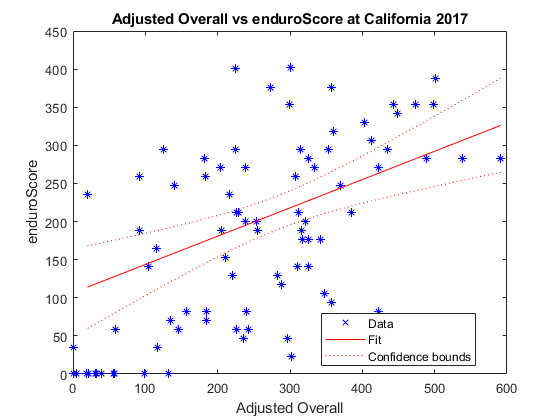

i = 52

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     83.037       20.938    3.9658    0.00014556
    x1             0.47081     0.085072    5.5342    2.9866e-07


Number of observations: 93, Error degrees of freedom: 91
Root Mean Squared Error: 89.2
R-squared: 0.252,  Adjusted R-Squared: 0.244
F-statistic vs. constant model: 30.6, p-value = 2.99e-07

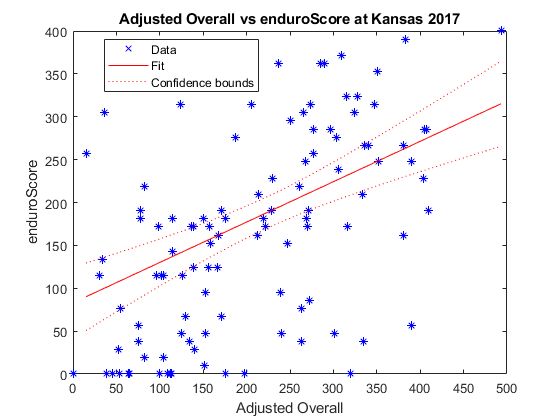

i = 53

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     45.082       26.544    1.6984      0.093134
    x1             0.54732     0.085439     6.406    8.2174e-09


Number of observations: 86, Error degrees of freedom: 84
Root Mean Squared Error: 95.3
R-squared: 0.328,  Adjusted R-Squared: 0.32
F-statistic vs. constant model: 41, p-value = 8.22e-09

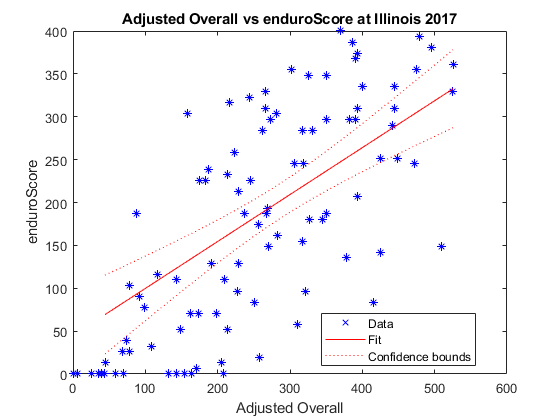

i = 54

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)     3.0427      32.658    0.093167       0.92602
    x1             0.62522     0.10282      6.0804    4.6349e-08


Number of observations: 77, Error degrees of freedom: 75
Root Mean Squared Error: 94.5
R-squared: 0.33,  Adjusted R-Squared: 0.321
F-statistic vs. constant model: 37, p-value = 4.63e-08

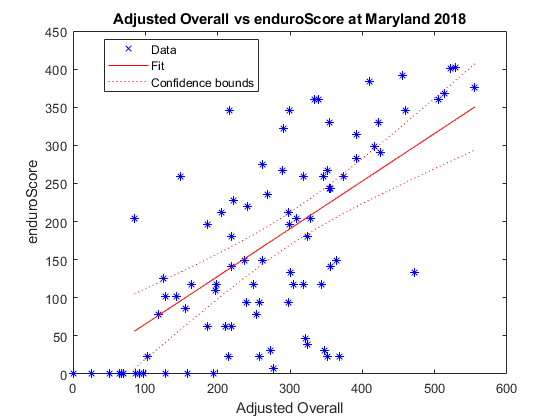

i = 55

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     7.5684       28.421    0.2663       0.79069
    x1             0.59302     0.090563    6.5482    4.9504e-09


Number of observations: 83, Error degrees of freedom: 81
Root Mean Squared Error: 85.9
R-squared: 0.346,  Adjusted R-Squared: 0.338
F-statistic vs. constant model: 42.9, p-value = 4.95e-09

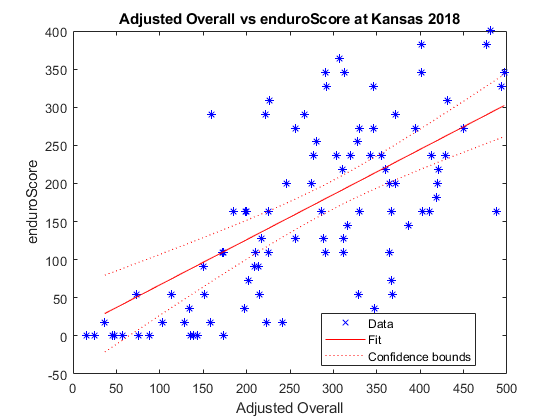

i = 56

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     17.281       25.019    0.69074       0.49173
    x1             0.59212     0.077183     7.6717    3.5457e-11


Number of observations: 82, Error degrees of freedom: 80
Root Mean Squared Error: 79.5
R-squared: 0.424,  Adjusted R-Squared: 0.417
F-statistic vs. constant model: 58.9, p-value = 3.55e-11

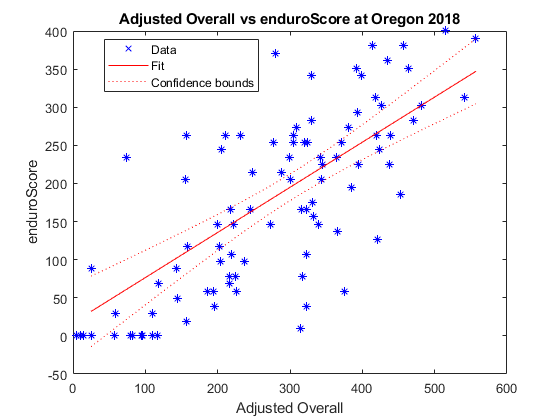

i = 57

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     14.602       33.84    0.43151       0.66736
    x1             0.61838     0.10837      5.706    2.2492e-07


Number of observations: 76, Error degrees of freedom: 74
Root Mean Squared Error: 105
R-squared: 0.306,  Adjusted R-Squared: 0.296
F-statistic vs. constant model: 32.6, p-value = 2.25e-07

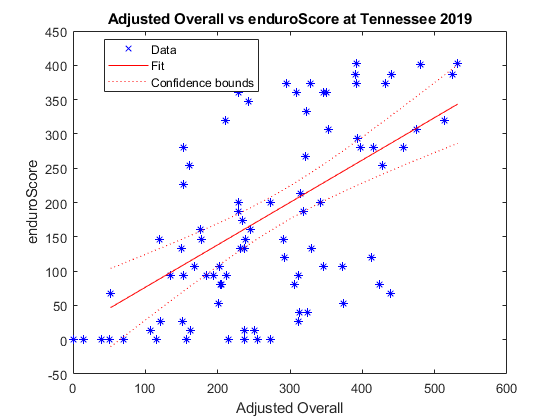

i = 58

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      72.91       35.795    2.0369      0.045241
    x1             0.40269     0.099626     4.042    0.00012844


Number of observations: 76, Error degrees of freedom: 74
Root Mean Squared Error: 90.6
R-squared: 0.181,  Adjusted R-Squared: 0.17
F-statistic vs. constant model: 16.3, p-value = 0.000128

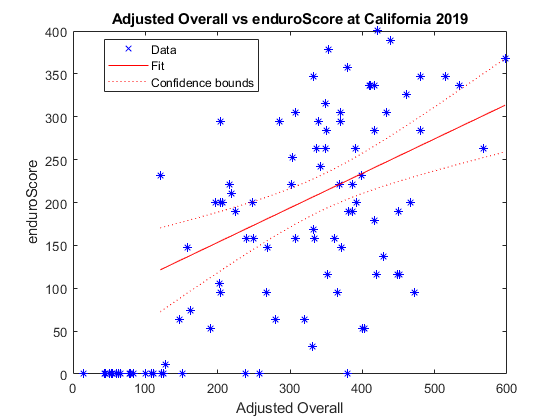

i = 59

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________

    (Intercept)    -26.508       31.696    -0.83631       0.40547
    x1              0.6067     0.087288      6.9505    8.8311e-10


Number of observations: 82, Error degrees of freedom: 80
Root Mean Squared Error: 84.5
R-squared: 0.377,  Adjusted R-Squared: 0.369
F-statistic vs. constant model: 48.3, p-value = 8.83e-10

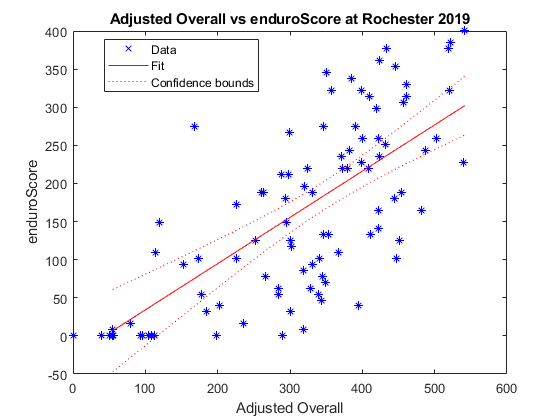

i = 60

rSqrs = zeros([size(allResults, 1) 1]);
for i = 22:size(allResults, 1) + 21
    tempModel = findResultCorrelation(allResults, i, "enduroScore");
    
    tempR = tempModel.Rsquared.Adjusted;
    
    i
    
    rSqrs(i) = tempR;
end

rSqrs = nonzeros(rSqrs)

rSqrs =     0.5491
    0.2448
    0.4998
   -0.0036
    0.2935
    0.2670
    0.4429
    0.2626
    0.2843
    0.3511


mean(rSqrs)

ans = 0.3111

std(rSqrs)

ans = 0.1125